# Example 2.3

First, we define the dataset. In this case $y = e^x$.

x=linspace(1,5,15)'

x =     1.0000
    1.2857
    1.5714
    1.8571
    2.1429
    2.4286
    2.7143
    3.0000
    3.2857
    3.5714


X = [ones(length(x),1) x]

X =     1.0000    1.0000
    1.0000    1.2857
    1.0000    1.5714
    1.0000    1.8571
    1.0000    2.1429
    1.0000    2.4286
    1.0000    2.7143
    1.0000    3.0000
    1.0000    3.2857
    1.0000    3.5714


y=exp(x);

Now, we first see what happens with linear regression:

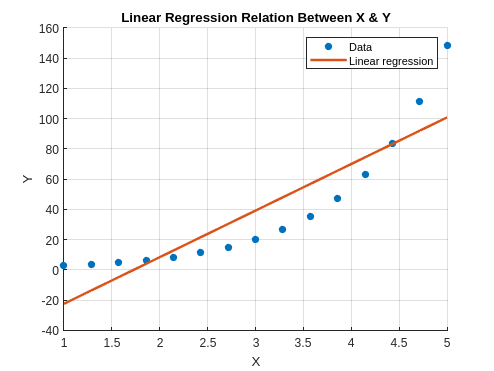

b1 = X\y;
yCalc1 = X*b1;
figure;

scatter(x,y,'filled')
hold on 
plot(x,yCalc1,'LineWidth',2)
xlabel('X')
ylabel('Y')
title('Linear Regression Relation Between X & Y')
legend('Data','Linear regression')
grid on
hold off

As we can see, the model does not fit the data addecuately. We can use a feature mapping and repeat the process with the transformed input:

X = feat_map(x)

X =     1.0000    1.0000    2.7183
    1.0000    1.2857    3.6173
    1.0000    1.5714    4.8135
    1.0000    1.8571    6.4054
    1.0000    2.1429    8.5238
    1.0000    2.4286   11.3427
    1.0000    2.7143   15.0938
    1.0000    3.0000   20.0855
    1.0000    3.2857   26.7281
    1.0000    3.5714   35.5674


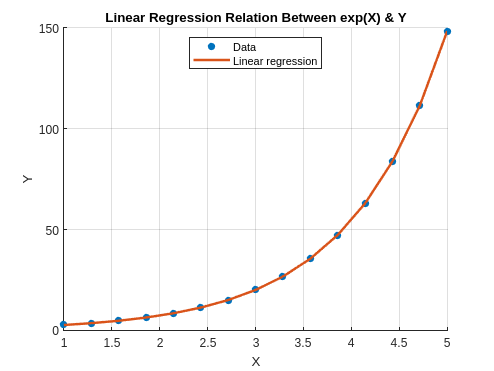


b2 = X\y;
yCalc2 = X*b2;

scatter(x,y,'filled')
hold on 
plot(x,yCalc2,'LineWidth',2)
xlabel('X')
ylabel('Y')
title('Linear Regression Relation Between exp(X) & Y')
legend('Data','Linear regression','Location','north')
grid on
hold off

As we can see, the model is now perfectly fitting the data!

function X=feat_map(x)
    X = [ones(size(x)) x exp(x)];
end